Aerial robot Lab report

Prepared by Melkamu Amare 

M2SAAS-2024

Submitted to: Mr. Islam Mahmoud

Universite Evry Paris-Saclay

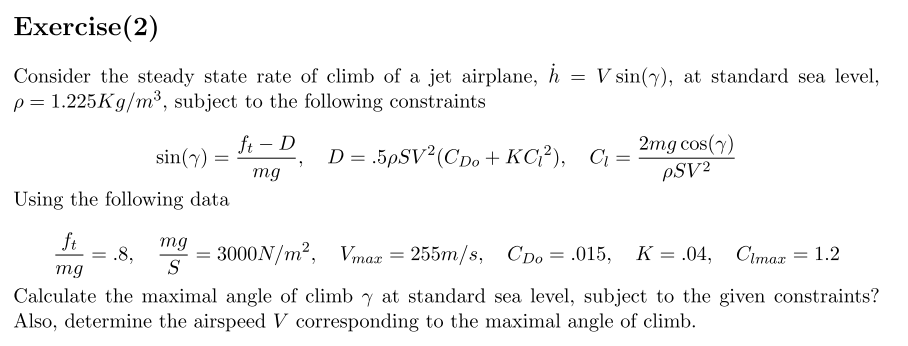

% Given data
ft_mg = 0.8;          % Thrust-to-weight ratio
mg_S = 3000;          % Weight per unit wing area (N/m^2)
V_max = 255;          % Maximum velocity (m/s)
CD0 = 0.015;          % Zero-lift drag coefficient
K = 0.04;             % Induced drag factor
rho = 1.225; % Air density at sea level (kg/m^3)
CLmax = 1.2;
% gamma = 0:0.1:pi/2;
% V = 0:1:255;

# First method(elimination/ approximation)

cos(gamma) ≈ 1

% Define the sin(gamma) function as a function of V
syms V

sin_gamma = ft_mg - (0.5*rho*V.^2.* ...
    (CD0 + K*(2*mg_S/(rho*V.^2)).^2))/(mg_S);
% assumption: gamma very small number and cos(gamma) = 1
gamma = 0

gamma = 0

V1 = 50:1:V_max;
for i = 1:length(V1)
    sin_g = eval(subs(sin_gamma, V1));
end
sg_max = islocalmax(sin_g);
gammad_max = asind(sin_g(sg_max)) % value of gamma in degree

gammad_max = 48.6778

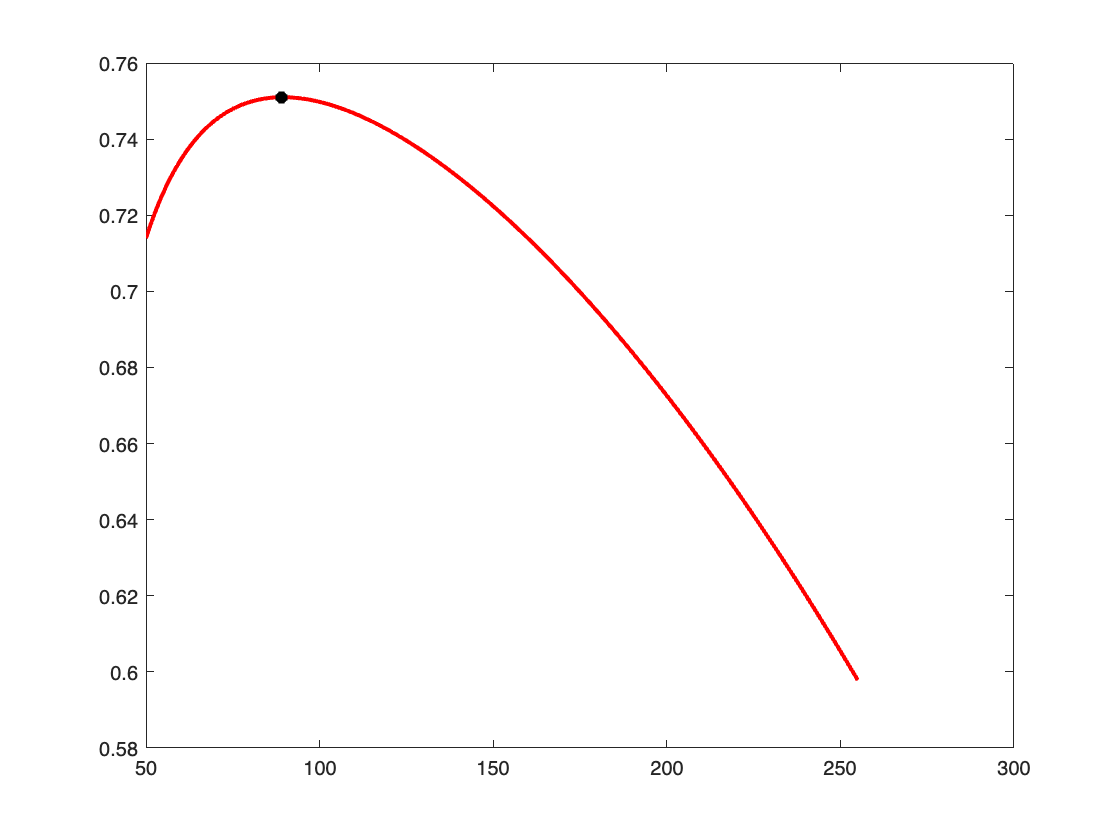


figure
plot(V1, sin_g, 'r-', LineWidth=2) % gamma plot in a range of velocities
hold on
plot(V1(sg_max), sin_g(sg_max), 'k*', LineWidth=3) % max point indicator
hold off

By indexing the value of velocity at max gamma, we can get the velocity of air at max angle.

Vair = V1(sg_max) % air speed at max angle gamma

Vair = 89

From the following formula, we know evrything except V; 

If we want to solve for the velocity V, we can rearrange it as:


$$V = \sqrt{\frac{2mg \cos(\gamma)}{C_L  \rho S}}$$


% velocity at max angle

Vmin = sqrt(2*mg_S*cosd(gammad_max)/(rho*CLmax)) % by substitution

Vmin = 51.9141

Here there is a value difference between the two values at max angle

gamma. I think, this is due to the assumption of taking gamma a very small

number in the first calculation and the value of gamma I got is large enough in

the second calculation.

==========================================================

# Second method (substitution)

We can also solve this the other way around by replacing **1 - sin^2(gamma) into cos^2(gamma)** 


$$\[
\sin(\gamma) = \frac{f t_-{\text{mg}} - 0.5 \rho V^2 \left( CD_0 + K \left( \frac{2 mg_-S \cos(\gamma)}{\rho V^2} \right)^2 \right)}{mg_-S}
\]$$


Substitute $ \( \cos^2(\gamma) = 1 - \sin^2(\gamma) \):$


$$\[
\sin(\gamma) = \frac{f t_-{\text{mg}} - 0.5 \rho V^2 \left( CD_0 + K \frac{4 mg_-S^2 (1 - \sin^2(\gamma))}{\rho^2 V^4} \right)}{mg_-S}
\]$$


Expanding and simplifying:


$$
\[
\sin(\gamma) = \frac{ft_-{\text{mg}} - 0.5 \rho V^2 CD_0 - 2 K \frac{mg_-S^2}{\rho V^2} (1 - \sin^2(\gamma))}{mg_-S}
\]$$


Multiply both sides by mg_S:


$$
\[
mg_-S * \sin(\gamma) = ft_-{\text{mg}} - 0.5 \rho V^2 CD_0 - 2 K \frac{mg_-S^2}{\rho V^2} + 2 K \frac{mg_-S^2}{\rho V^2} \sin^2(\gamma)
\]
$$


Rearrange the equation:


$$

\[
mg_-S \sin(\gamma) - 2 K \frac{mg_-S^2}{\rho V^2} \sin^2(\gamma) = f t_-{\text{mg}} - 0.5 \rho V^2 CD_0 - 2 K \frac{mg_S^2}{\rho V^2}
\]
$$


Now, we have a quadratic equation in sin(gamma):


$$

\[
A \sin^2(\gamma) + B \sin(\gamma) + C = 0
\]

where:

\[
A = -2 K \frac{mg_-S^2}{\rho V^2}, \quad B = mg_-S, \quad C = -\left( ft_-{\text{mg}} - 0.5 \rho V^2 CD_0 - 2 K \frac{mg_-S^2}{\rho V^2} \right)
\]$$


The solution for sin(gamma) using the quadratic formula is:


$$

\[
\sin(\gamma) = \frac{-B \pm \sqrt{B^2 - 4AC}}{2A}
\]$$


A = -2 * K * (mg_S^2) / (rho * V^2);  % Coefficient of sin^2(gamma)
B = mg_S;                            % Coefficient of sin(gamma)
C = -(ft_mg - 0.5 * rho*V^2*CD0 - 2 * K * (mg_S^2) / (rho * V^2));  % Constant term

root0 = B^2 - 4 * A * C;
% If the discriminant (root0) is non-negative, the quadratic formula is used to compute the two ...
% possible solutions for sin(gamma)

 sin_gamma1 = (-B + sqrt(root0)) / (2 * A);
 sin_gamma2 = (-B - sqrt(root0)) / (2 * A);

V1 = 50:1:V_max;
for i = 1:length(V1)
    A1 = eval(subs(A, V1));
    C1 = eval(subs(C, V1));
    
    
    root1 = B^2 - 4*A1.*C1;

    % check for complex results, if root1 < 0, there will be a complex
    % value and it is unnecessary
    if root1>=0
        sin_g1 = (-B + sqrt(root1))./(2 * A1);
        sin_g2 = (-B - sqrt(root1))./(2 * A1);
    end
end

sg_max1 = islocalmax(sin_g1);
sg_max2 = islocalmax(sin_g2);

if abs(sin_g1) <= 1
    gammad_max1 = asind(sin_g1(sg_max1)) % value of gamma in degree
else
    disp('The result does not look like a sign function value')
end

gammad_max1 = -2.7895

Vair1 = V1(sg_max1) % air speed at max angle gamma by indexing

Vair1 = 89

Vair11 = sqrt(2*mg_S*cosd(gammad_max1)/(rho*CLmax)) % by substitution

Vair11 = 63.8498

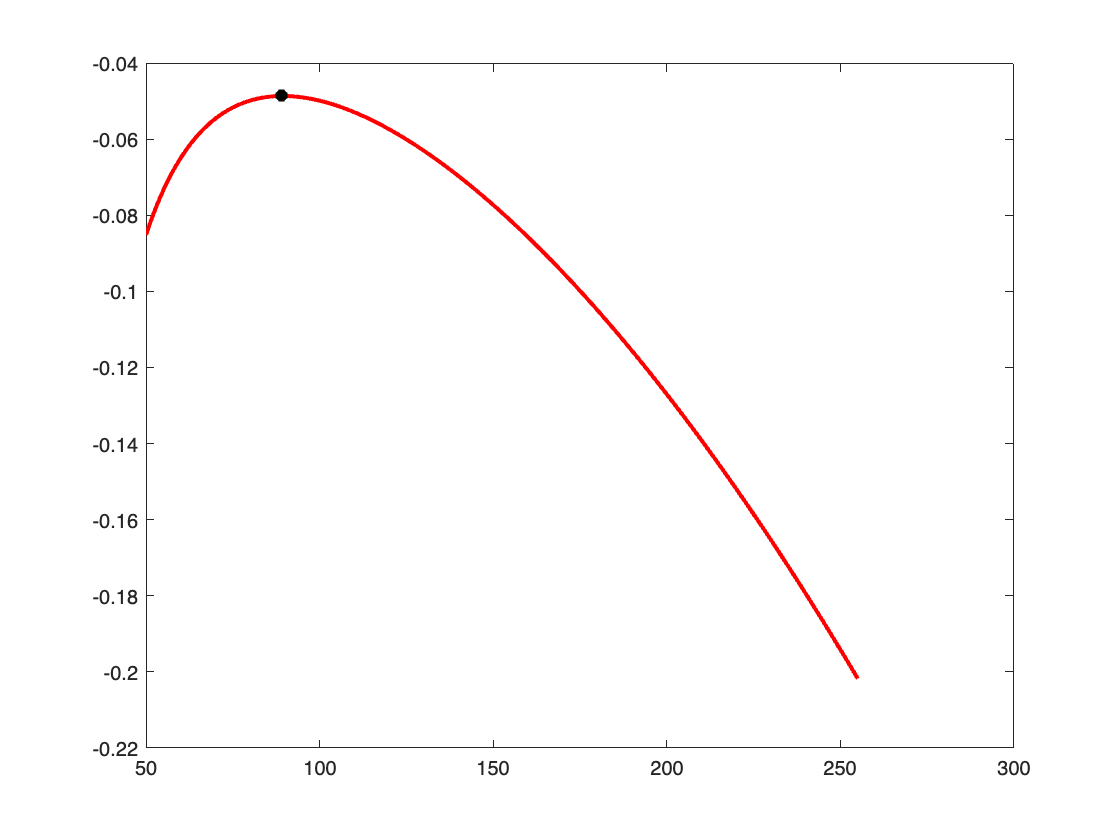


figure
plot(V1, sin_g1, 'r-', LineWidth=2) % gamma plot in a range of velocities
hold on
plot(V1(sg_max1), sin_g1(sg_max1), 'k*', LineWidth=3) % max point indicator
hold off

% The second root sin_g2 has no local maxima, and its value for <sin> is ...
% greater than 1; so, it can't be our solution
if abs(sin_g2) <= 1
    gammad_max2 = asind(sin_g2(sg_max2)) % value of gamma in degree
else
    disp('The result does not look like a sign function value')
end

The result does not look like a sign function value


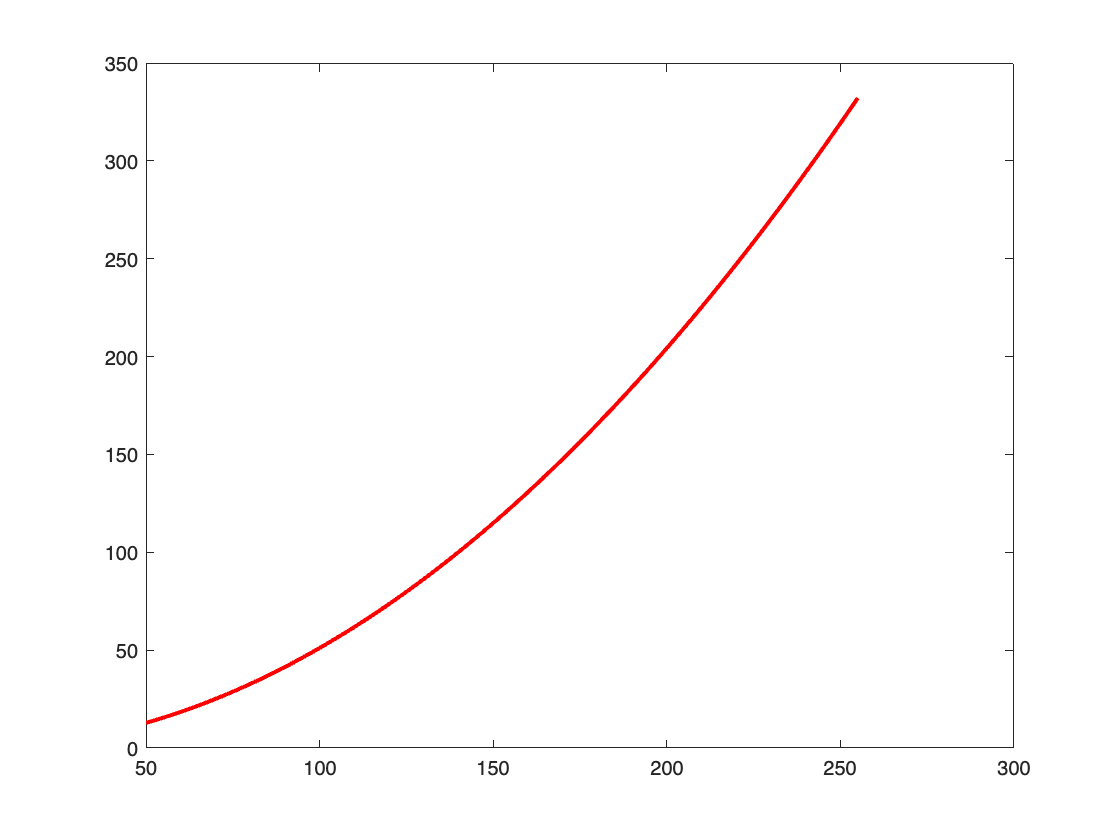


figure
plot(V1, sin_g2, 'r-', LineWidth=2) % gamma plot in a range of velocities
hold on
plot(V1(sg_max2), sin_g2(sg_max2), 'k*', LineWidth=3) % max point indicator
hold off

The plot justified that no max value for this graph is found, it is exponentially increasing function plot

**Compared to the previous (elimination method), the value of the air velocity at max angle is the same, while the value of the max angle is totally different. One thing I didn't figure out here is, the value of sign(gamma) is negative in this option while the it was positive in the previous method; why the sign difference is happened? and what is the meaning of the negative sign? I just tried to interpret it by relating with clockwise/ anti-clockwise measurement of angles, however I am not sure about that.** 